%% Vegyes Modulációs (BPSK-QPSK-BPSK) Konvolúciós Kódolás Szimuláció
% Ez a szkript demonstrálja az "Unequal Error Protection" (UEP) és a 
% Viterbi Horgony-effektus hatását a bithibaarányra (BER).

clear; clc; close all;

%% 1. Rendszer paraméterek
K = 7; % Kényszerhossz
poly = [171 133]; % Ipari standard polinomok
trellis = poly2trellis(K, poly);

dataLen = 1000;         % Hasznos adatbitek száma egy keretben
tailLen = K - 1;        % Tail (farok) bitek a regiszter kiürítéséhez
% R=1/2 miatt a kódolt bitszám pontosan a duplája lesz:
codedLen = (dataLen + tailLen) * 2; 

% Vegyes moduláció beállítása
% Mennyi kódolt bitet küldjünk BPSK-val az elején és a végén?
% (Fontos, hogy a maradék QPSK bitek száma páros legyen!)
nBpskBits = 200; % Az első és utolsó 200 kódolt bit BPSK lesz
nQpskBits = codedLen - 2*nBpskBits; 

snr_dB_array = 0:0.5:4; % SNR tartomány
max_keret = 1000;       % Hány keretet szimuláljunk SNR pontonként

% Eredménytárolók
ber_pure_qpsk = zeros(size(snr_dB_array));
ber_mixed     = zeros(size(snr_dB_array));

fprintf('--- Szimuláció indítása: Tiszta QPSK vs. BPSK-QPSK-BPSK ---\n');

--- Szimuláció indítása: Tiszta QPSK vs. BPSK-QPSK-BPSK ---


fprintf('Kódolt kerethossz: %d bit\n', codedLen);

Kódolt kerethossz: 2012 bit


fprintf('Ebből BPSK (eleje/vége): %d - %d bit\n', nBpskBits, nBpskBits);

Ebből BPSK (eleje/vége): 200 - 200 bit


fprintf('Ebből QPSK (közepe)    : %d bit\n\n', nQpskBits);

Ebből QPSK (közepe)    : 1612 bit




for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_pure = 0;
    hiba_mixed = 0;
    
    % Zajteljesítmény LLR számításhoz
    nv = 10^(-snr/10); 
    
    for k = 1:max_keret
        %% --- ADATGENERÁLÁS ÉS KÓDOLÁS ---
        data = randi([0 1], dataLen, 1);
        
        % Farok (Tail) bitek (csupa 0) hozzáfüzése, hogy a Trellis visszatérjen a 0 állapotba
        dataWithTail = [data; zeros(tailLen, 1)]; 
        
        % Konvolúciós kódolás
        codedData = convenc(dataWithTail, trellis);
        
        %% --- 1. RENDSZER: TISZTA QPSK (REFERENCIA) ---
        % Minden kódolt bitet 2-esével párosítunk QPSK szimbólumokhoz
        cD_pure = reshape(codedData, 2, [])';
        symIdx_pure = bi2de(cD_pure, "left-msb");
        tx_pure = pskmod(symIdx_pure, 4, pi/4);
        
        % Csatorna zaj
        rx_pure = awgn(tx_pure, snr, 'measured');
        
        % Demoduláció és LLR (Valószínűség) számítás
        llr_pure_pairs = pskdemod(rx_pure, 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        llr_pure_stream = llr_pure_pairs(:); % Vektorrá alakítás
        
        % Viterbi Dekódolás ('term' mód, mert farokbiteket használtunk!)
        dec_pure_full = vitdec(llr_pure_stream, trellis, 100, 'term', 'unquant');
        dec_pure = dec_pure_full(1:dataLen); % Tail bitek levágása
        
        % Hibaszámítás
        hiba_pure = hiba_pure + biterr(data, dec_pure);
        
        %% --- 2. RENDSZER: VEGYES MODULÁCIÓ (BPSK-QPSK-BPSK) ---
        % Szegmentáljuk a kódolt biteket
        codedStart = codedData(1 : nBpskBits);
        codedMid   = codedData(nBpskBits+1 : end-nBpskBits);
        codedEnd   = codedData(end-nBpskBits+1 : end);
        
        % Moduláció: BPSK a széleken (0 és 1 állapot), QPSK középen
        tx_start = pskmod(codedStart, 2, 0); % BPSK
        
        cD_mid = reshape(codedMid, 2, [])';
        symIdx_mid = bi2de(cD_mid, "left-msb");
        tx_mid = pskmod(symIdx_mid, 4, pi/4); % QPSK
        
        tx_end = pskmod(codedEnd, 2, 0);     % BPSK
        
        % Csatorna zaj a szegmenseken
        rx_start = awgn(tx_start, snr, 'measured');
        rx_mid   = awgn(tx_mid,   snr, 'measured');
        rx_end   = awgn(tx_end,   snr, 'measured');
        
        % Demoduláció (LLR visszanyerése külön-külön)
        llr_start = pskdemod(rx_start, 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        llr_mid_pairs = pskdemod(rx_mid, 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        llr_mid_stream = llr_mid_pairs(:);
        llr_end = pskdemod(rx_end, 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        % LLR stream újraegyesítése a Viterbi számára
        llr_mixed_stream = [llr_start; llr_mid_stream; llr_end];
        
        % Viterbi Dekódolás
        dec_mixed_full = vitdec(llr_mixed_stream, trellis, 100, 'term', 'unquant');
        dec_mixed = dec_mixed_full(1:dataLen);
        
        % Hibaszámítás
        hiba_mixed = hiba_mixed + biterr(data, dec_mixed);
    end
    
    % BER számítása az aktuális SNR ponton
    ber_pure_qpsk(snr_idx) = hiba_pure / (max_keret * dataLen);
    ber_mixed(snr_idx)     = hiba_mixed / (max_keret * dataLen);
    
    fprintf('SNR = %2.1f dB | BER QPSK: %e | BER Vegyes: %e\n', ...
            snr, ber_pure_qpsk(snr_idx), ber_mixed(snr_idx));
end

SNR = 0.0 dB | BER QPSK: 1.496920e-01 | BER Vegyes: 1.207570e-01
SNR = 0.5 dB | BER QPSK: 8.418400e-02 | BER Vegyes: 6.730400e-02
SNR = 1.0 dB | BER QPSK: 3.926100e-02 | BER Vegyes: 3.128100e-02
SNR = 1.5 dB | BER QPSK: 1.406000e-02 | BER Vegyes: 1.159800e-02
SNR = 2.0 dB | BER QPSK: 5.372000e-03 | BER Vegyes: 3.834000e-03
SNR = 2.5 dB | BER QPSK: 1.284000e-03 | BER Vegyes: 1.060000e-03
SNR = 3.0 dB | BER QPSK: 3.920000e-04 | BER Vegyes: 2.160000e-04
SNR = 3.5 dB | BER QPSK: 9.600000e-05 | BER Vegyes: 1.040000e-04
SNR = 4.0 dB | BER QPSK: 3.200000e-05 | BER Vegyes: 6.000000e-06


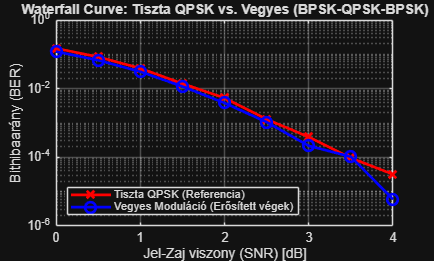


%% --- Eredmények kirajzolása ---
figure('Name', 'UEP - Viterbi Anchor Effect', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_pure_qpsk, 'r-x', 'LineWidth', 2, 'MarkerSize', 8);
hold on;
semilogy(snr_dB_array, ber_mixed, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('Waterfall Curve: Tiszta QPSK vs. Vegyes (BPSK-QPSK-BPSK)');
xlabel('Jel-Zaj viszony (SNR) [dB]');
ylabel('Bithibaarány (BER)');
legend('Tiszta QPSK (Referencia)', 'Vegyes Moduláció (Erősített végek)', 'Location', 'southwest');